# Fitting the MZI spectrum

Use the Matlab code below to download and plot the measurement data, and curve fit it to the MZI transfer function.

You will need to make adjustments to the initial parameters for the fitting function. Specifically, change the following line:

nx_init = [2.38, -1, 0]; %%%%%%%%%%%% CHANGE THE FIRST PARAMETER

Check your answer when you think you have a good fit. 

Please note that this code fits the response using the MZI transfer function. This function includes the path length difference, ∆L. This must match the design, in order to have meaningful results. 

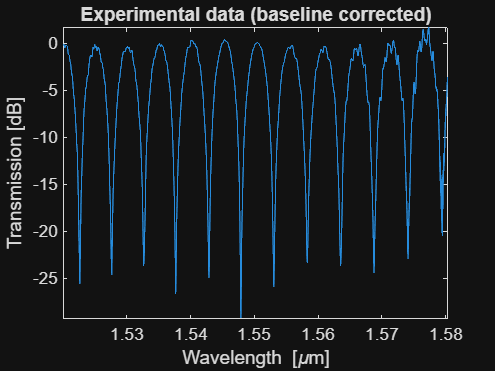


% Enter the Dropbox URL here.  Make sure it has a =1 at the end:
url = 'https://www.dropbox.com/s/1rvjfef4jqybc12/ZiheGao_MZI2_271_Scan1.mat?dl=1';
dL = 111.915;  % [micron] Path length difference in the MZI

PORT=1; % Which Fibre array port is the output connected to?

a=websave('mzi.mat',url); % get data from Dropbox
load('mzi.mat');

% Data is stored in variable "scanResults".
% There are two columns - wavelength (1), and amplitude (2)
lambda=scanResults(1,PORT).Data(:,1)/1e9;
amplitude=scanResults(1,PORT).Data(:,2);

% Curve fit data to a polynomial for baseline correction
p=polyfit((lambda-mean(lambda))*1e6, amplitude, 4);
amplitude_baseline=polyval(p,(lambda-mean(lambda))*1e6); 

% Perform baseline correction to flatten the spectrum
% Use the curve polynomial, and subtract from original data
amplitude_corrected = amplitude - amplitude_baseline;
amplitude_corrected = amplitude_corrected + max(amplitude_baseline) - max(amplitude);
figure;
plot (lambda*1e6, amplitude_corrected);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (baseline corrected)');

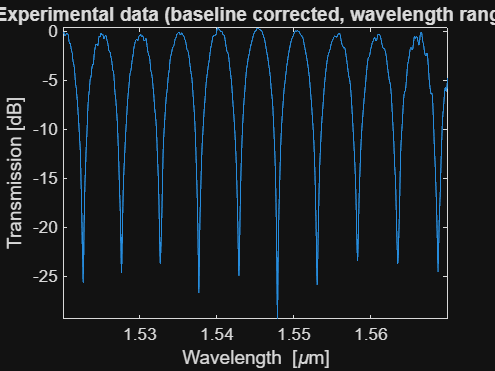


% data only within the wavelength range of interest.
lambda_min = min(lambda);	% Can limit the analysis to a range of wavelengths
lambda_max = max(lambda);   %  if the data on the edges is noisy

lambda_max = 1.57e-6; %Set this to a specific value to truncate nosiy data

lambda1=lambda_min:min(diff(lambda)):lambda_max;
amplitude=interp1(lambda, amplitude_corrected, lambda1,'linear');
lambda=lambda1;
amplitude(find(amplitude==-inf))=-50;  % check if there are -infinity data points
figure;
plot (lambda*1e6, amplitude);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (baseline corrected, wavelength range)');

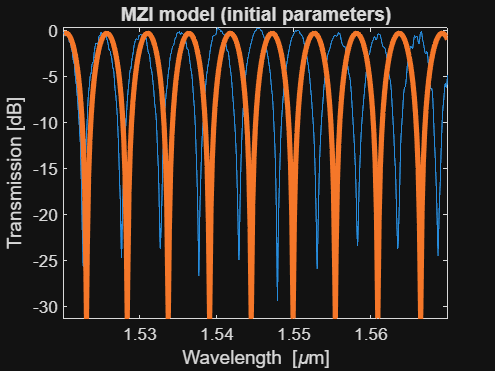



% Define the MZI transfer function
% - as a Taylor expansion around the central wavelength
% - Use units of [microns] – keeps the variables closer to 1.
% - These make the curve fitting easier.
lambda0 = mean(lambda)*1e6;		
% use Matlab anonymous functions
% effective index:
neff = @(nx, lambda) ...
		(nx(1) + nx(2).*(lambda-lambda0) + nx(3).*(lambda-lambda0).^2); 
% neff([2.4, -1, 0], 1.56)  % test it.
% alpha = 1e-3;  % propagation loss [micron^-1]
% complex propagation constant
beta = @(nx, alpha, lambda) ...
		(2*pi*neff(nx, lambda)./lambda - 1i*alpha/2*ones(1,length(lambda)) );
% beta([2.4, -1, 0], 1e-3, [1.56, 1.57]) % test it.
% MZI transfer function
T_MZI = @(X, lambda) ...
        (10*log10( 0.25* abs(1+exp(-1i*beta(X(1:3), X(4), lambda)*dL)).^2) +X(5) );
% T_MZI([2.4, -1, 0, 1e-3], [1.56, 1.57]) % test it.

% initial function for fitting
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
nx_init = [2.38, -1, 0];   %%%%%%%%%%%% CHANGE THE FIRST PARAMETER
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
alpha_init = 1e-3;  % propagation loss [micron^-1]
x0=[nx_init, alpha_init, 0];
figure;
plot (lambda*1e6, amplitude);
hold all;
plot(lambda*1e6, T_MZI(x0, lambda*1e6),'LineWidth',3);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('MZI model (initial parameters)');


% Curve fit:  
[xfit,resnorm] = lsqcurvefit(T_MZI,x0,lambda*1e6,amplitude);


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 5.000000e+02.



xfit

xfit =     2.3759   -0.9182   11.1399    0.0179    0.2213


r=corrcoef(amplitude,T_MZI(xfit, lambda*1e6));
r2=r(1,2).^2

r2 = 0.1965

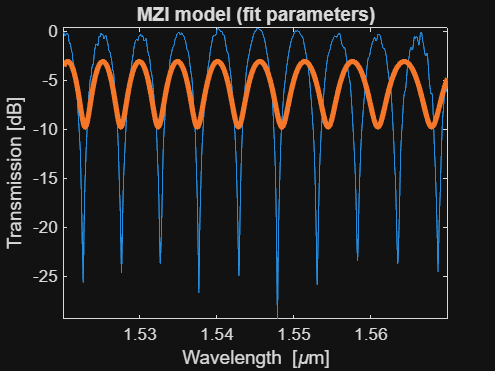


figure;
plot (lambda*1e6, amplitude);
hold all;
plot(lambda*1e6, T_MZI(xfit, lambda*1e6),'LineWidth',3); 
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('MZI model (fit parameters)');


% Check if the fit is good.  If so, find ng
if (ge(r2,0.8))
  % plot ng curve
  figure;
  neff_fit = neff(xfit(1:3),lambda*1e6);
  dndlambda=diff(neff_fit)./diff(lambda); dndlambda=[dndlambda, dndlambda(end)];
  ng=(neff_fit - lambda .* dndlambda);
  plot(lambda*1e6, ng, 'LineWidth',4);
  xlabel ('Wavelength [\mum]');
  ylabel ('Group index, n_g');
  axis tight
  title ('Group index (from MZI fit)');
    
  % waveguide parameters at lambda0
  ng0 = xfit(1) - lambda0*xfit(2)
end

Check

assert(ge(r2,0.8), 'The goodness of it is low.')

Error using assert
The goodness of it is low.

The goodness-of-fit is low.  The R^2 value should be greater than 0.8.  Adjust the initial conditions until the fit quality is higher.

Make sure you have a variable named `r2` for the check to work properly.